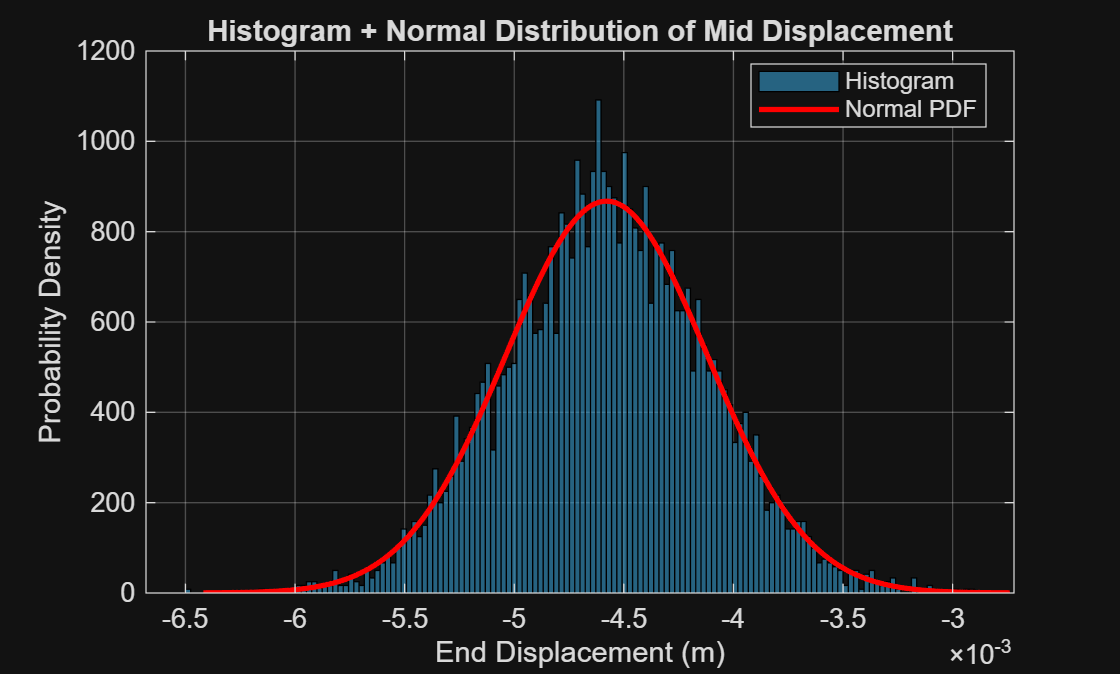

clc;
clear all;

number_of_runs = 5000;
EI = 4.2e7;
P_mu = 10000;
COV = 0.1;  % Coefficient of variation (10%)
P_sigma = (COV * P_mu)^2;
P_samples = mvnrnd(P_mu, P_sigma, number_of_runs);

mid_displacement = zeros(number_of_runs,1);
mean_vals = zeros(number_of_runs,1);  % For convergence of mean
std_vals = zeros(number_of_runs,1);   % For convergence of std

for n = 1:number_of_runs
    P = P_samples(n);  % Sampled point load

    % Beam parameters
    L_beam = 10; 
    N = 5; 
    Nodes = N + 1;
    partLength = L_beam / N;

    % DOF mapping
    dof = zeros(N, 4);
    for i = 1:N
        dof(i,:) = [2*i - 1, 2*i, 2*i + 1, 2*i + 2];
    end

    % Global stiffness matrix
    Keq = zeros(Nodes*2);
    for i = 1:N
        Le = partLength;
        k = (EI / Le^3) * ...
            [12, 6*Le, -12, 6*Le;
             6*Le, 4*Le^2, -6*Le, 2*Le^2;
            -12, -6*Le, 12, -6*Le;
             6*Le, 2*Le^2, -6*Le, 4*Le^2];

        for j = 1:4
            for p = 1:4
                Keq(dof(i,j), dof(i,p)) = Keq(dof(i,j), dof(i,p)) + k(j,p);
            end
        end
    end

    % Apply external load at node 6 (DOF 11)
    F = zeros(Nodes*2, 1);
    F(5) = -P;

    % Boundary conditions
    fixed_dofs = [1, 11];
    free_dofs = setdiff(1:Nodes*2, fixed_dofs);

    % Solve system
    K_reduced = Keq(free_dofs, free_dofs);
    F_reduced = F(free_dofs);
    d = zeros(Nodes*2, 1);
    d(free_dofs) = K_reduced \ F_reduced;

    % Store vertical displacement at endspan (Node 6 = DOF 11)
    mid_displacement(n) = d(5);

    % Compute running mean and std
    mean_vals(n) = mean(mid_displacement(1:n));
    std_vals(n) = std(mid_displacement(1:n));
end

mu_d = mean(mid_displacement);
sigma_d = std(mid_displacement);
x = linspace(mu_d - 4*sigma_d, mu_d + 4*sigma_d, 1000);
pdf_values = normpdf(x, mu_d, sigma_d);

figure;
histogram(mid_displacement, 150, 'Normalization', 'pdf', ...
    'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'k', 'DisplayName', 'Histogram');
hold on;
plot(x, pdf_values, 'r-', 'LineWidth', 2, 'DisplayName', 'Normal PDF');
xlabel('End Displacement (m)');
ylabel('Probability Density');
title('Histogram + Normal Distribution of Mid Displacement');
legend('Location', 'best');
grid on;

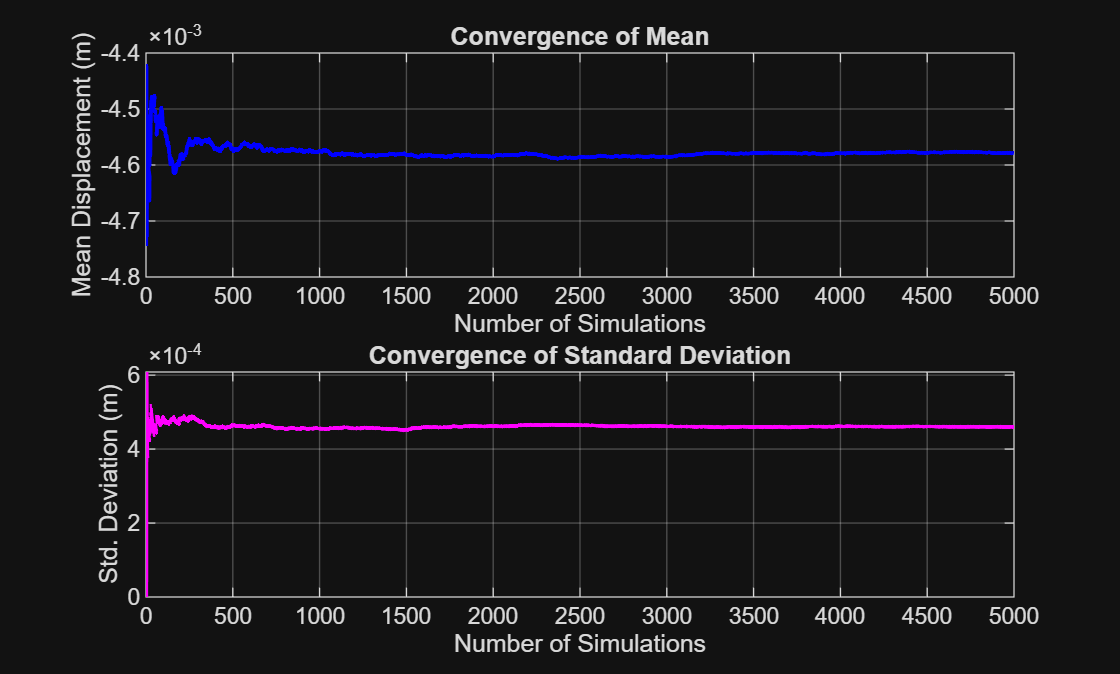



% --- Plot 2: Convergence of Mean and Std Dev ---
figure;
subplot(2,1,1)
plot(1:number_of_runs, mean_vals, 'b', 'LineWidth', 1.5);
xlabel('Number of Simulations');
ylabel('Mean Displacement (m)');
title('Convergence of Mean');
grid on;

subplot(2,1,2)
plot(1:number_of_runs, std_vals, 'm', 'LineWidth', 1.5);
xlabel('Number of Simulations');
ylabel('Std. Deviation (m)');
title('Convergence of Standard Deviation');
grid on;


% --- Print final stats ---
fprintf('Final Mean of Mid Displacement: %.4f m\n', mu_d);

Final Mean of Mid Displacement: -0.0046 m


fprintf('Final Std Dev of Mid Displacement: %.4f m\n', sigma_d);

Final Std Dev of Mid Displacement: 0.0005 m
